# STI for TS images

Script to calculate STI for time series images.

## Inputs & arguments

- **time series images**: The images at different dates and years (say n images).

- mask: Mask file for each year.

- **spatilal lag**: The number of pixels to expand from centroid.

## outputs:

- **STI series images**: The STI index at each pixel and date (return n-1 images).

## I / O

% Choose mask file.
[File, Path]=uigetfile({'*.tif'},'Choose mask file.','Multiselect','off','/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[mask, R0] = geotiffread(strcat(Path, File));
[x,y] = size(mask);

% Choose time series imagery.
[file, path] = uigetfile({'*.tif'}, 'Choose imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/');
[~, fileLength] = size(file);
IM = zeros(x,y,fileLength);
dates= zeros(1,fileLength);

% Read & mask time series images and batch NDVI.
for num = 1:fileLength
    [temp, R1] = geotiffread(strcat(path, char(file(num))));
    DOYtemp = char(file(num));
    dates(num) = str2num(DOYtemp(7:end-4));
    NIR = double(temp(:,:,4));
    R = double(temp(:,:,3));
    ndvi = (NIR - R) ./ (NIR + R);
    %% applying mask.
    ndvi(mask ~= 1) = nan;
    IM(:,:,num) = ndvi;
end

% Choose harmonic models.
[fileH, pathH] = uigetfile({'*.tif'}, 'Choose harmonic params imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[~, fileLengthH] = size(fileH);
paramsH = zeros(x,y,fileLengthH);
for num = 1:fileLengthH
    paramsH(:,:,num) = geotiffread(strcat(pathH, char(fileH(num))));
end

% Output results
residualArr = nan(x,y,fileLength);
harmonicArr = nan(x,y,fileLength);
STI = zeros(x,y,fileLength - 1);


## Batch NDVI and harmonic modeling

for num = 1:fileLength
    DOY = dates(num);
    beta0 = paramsH(:,:,1);
    beta1 = paramsH(:,:,2);
    beta2 = paramsH(:,:,3);
    beta3 = paramsH(:,:,4);
    angle = 2 * pi * DOY / 365;
    tempHar = beta0 + beta1 .* DOY + beta2 * cos(angle) + beta3 * sin(angle);
    tempHar(mask ~= 1) = nan;
    harmonicArr(:,:,num) = tempHar;
end
residualArr = IM - harmonicArr;

## Calculating ST Moran's I

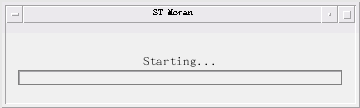

lags = 1;
lagt = 1;
tic
wb = waitbar(0, 'Starting...');
set(wb,'Name','ST Moran');

for num = 2:fileLength
    im1 = residualArr(:,:,num-1);
    im2 = residualArr(:,:,num);
    STI(:,:,num-1) = STMoran(im1, mask, im2, mask, lags, lagt);
    waitbar(double(num-1)/(fileLength-1),wb,strcat(num2str(double(num-1)/(fileLength-1) * 100),'%.'));
end

在当前文件夹或 MATLAB 路径中未找到 'STMoran'，但它位于:
 /home/dk/文档/Tutor/Moran/code

更改 MATLAB 当前文件夹 或 将其文件夹添加到 MATLAB 路径。

toc